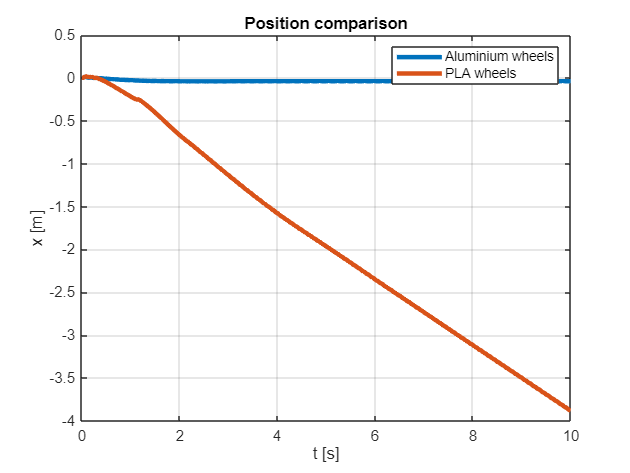

run("complete/complete_parameters.m")
% Initial state
X0 = [0; 0; 5*pi/180; 0];

% ALU WHEELS

Tsim = 10;
t = 0:0.001:Tsim;
v_ref = 0 * ones(size(t));
input_signal = [t' v_ref'];
out = sim("complete/complete_robot_sim.slx");
al_x_v = out.simout.signals.values(:,1); 
al_dx_v = out.simout.signals.values(:,2);
al_dxmsim_v = out.speed_measured.signals.values();
al_theta_v = out.simout.signals.values(:,3);
al_dtheta_v = out.simout.signals.values(:,4);
al_theta_mes = out.theta_measure.signals.values();
al_theta_target = out.theta_target.signals.values();
al_torque_v = out.torque.signals.values();
al_domega = out.domega.signals.values();
al_ddx = out.ddx.signals.values(1,:);
al_t_v = out.tout;
al_t_vd = out.domega.time;

% PLA WHEELS
J_w = 7.615e-5;
m_w = 0.083;
P = [m_b;m_w;l;g;r;J_w;J_b;rho;phi;T_s];

out = sim("complete/complete_robot_sim.slx");
pl_x_v = out.simout.signals.values(:,1); 
pl_dx_v = out.simout.signals.values(:,2);
pl_dxmsim_v = out.speed_measured.signals.values();
pl_theta_v = out.simout.signals.values(:,3);
pl_dtheta_v = out.simout.signals.values(:,4);
pl_theta_mes = out.theta_measure.signals.values();
pl_theta_target = out.theta_target.signals.values();
pl_torque_v = out.torque.signals.values();
pl_domega = out.domega.signals.values();
pl_ddx = out.ddx.signals.values(1,:);
pl_t_v = out.tout;
pl_t_vd = out.domega.time;

data = readmatrix('./data/pla_wheel.csv');
tm_v = data(:,1)/1000;
dxm_v = data(:,4);
dx_targetm_v = data(:,3);
xm_v = data(:,7)/1000;
thetam_v = data(:,6);
theta_targetm_v = data(:,5);


%% Compare Aluminium and PLA wheels

% Position
figure;
plot(al_t_v, al_x_v, "LineWidth", 3);
hold on;
plot(pl_t_v, pl_x_v, "LineWidth", 3);
xlabel('t [s]');
ylabel('x [m]');
title('Position comparison');
legend('Aluminium wheels','PLA wheels');
grid on;

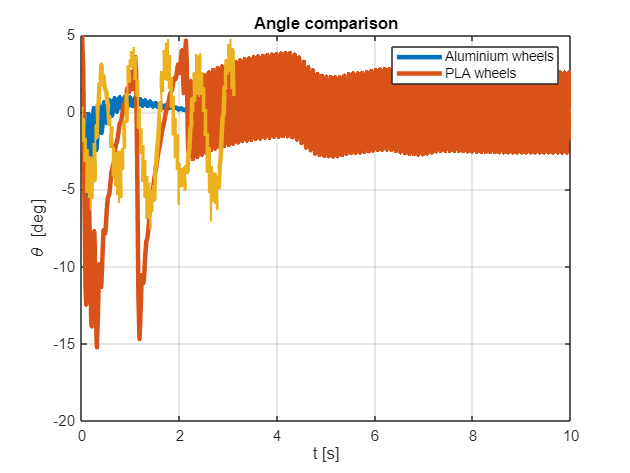



% Angle
figure;
plot(al_t_v, al_theta_v*180/pi, "LineWidth", 3);
hold on;
plot(pl_t_v, pl_theta_v*180/pi, "LineWidth", 3);
plot(tm_v, thetam_v, "LineWidth", 3);
xlabel('t [s]');
ylabel('\theta [deg]');
title('Angle comparison');
legend('Aluminium wheels','PLA wheels');
grid on;

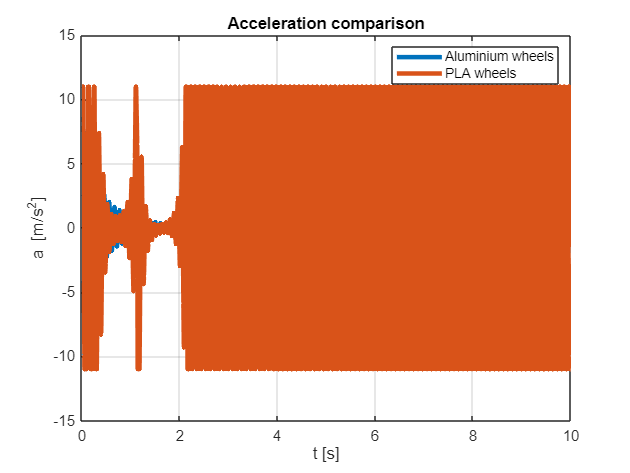



% Acceleration
figure;
plot(al_t_v, al_ddx, "LineWidth", 3);
hold on;
plot(pl_t_v, pl_ddx, "LineWidth", 3);
xlabel('t [s]');
ylabel('a [m/s^2]');
title('Acceleration comparison');
legend('Aluminium wheels','PLA wheels');
grid on;

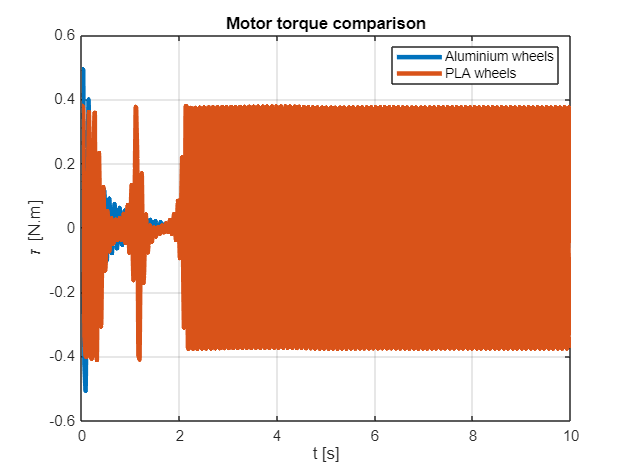



% Torque
figure;
plot(al_t_v, al_torque_v, "LineWidth", 3);
hold on;
plot(pl_t_v, pl_torque_v, "LineWidth", 3);
xlabel('t [s]');
ylabel('\tau [N.m]');
title('Motor torque comparison');
legend('Aluminium wheels','PLA wheels');
grid on;

X0 = [0; 0; 0; 0];

% Trapezoidal/Triangular velocity reference
v_peak = 0.7;        % m/s
Tsim = 6;
t = 0:0.001:Tsim;

t_rise = 2;
t_fall = 2;
t_tot  = 5;

t_flat = t_tot - (t_rise + t_fall);

v_ref = zeros(size(t));

for i = 1:length(t)

    if t(i) < t_rise
        % Ramp up
        v_ref(i) = v_peak * t(i) / t_rise;

    elseif t(i) < (t_rise + t_flat)
        % Constant section
        v_ref(i) = v_peak;

    elseif t(i) < t_tot
        % Ramp down
        v_ref(i) = v_peak * (t_tot - t(i)) / t_fall;

    else
        % After profile ends
        v_ref(i) = 0;
    end

end

input_signal = [t' v_ref'];
out = sim("complete/complete_robot_sim.slx");

theta_v = out.simout.signals.values(:,3);
theta_mes = out.theta_measure.signals.values();
x_v = out.simout.signals.values(:,1); 
dx_v = out.simout.signals.values(:,2); 
dtheta_v = out.simout.signals.values(:,4);
torque_v = out.torque.signals.values();
domega = out.domega.signals.values();
ddx = out.ddx.signals.values(1,:);
theta_target = out.theta_target.signals.values();
t_v = out.tout;
